
% 手动数所有周期数 %

close all
clear all
colors=npg(10); % Ten basic colors 
tpi = 2*pi;

maindir='\\Artemis-pc\e\Data\2024-04-\Abs-306\';
main_dir_0=maindir;
load([maindir,'\population.mat']);


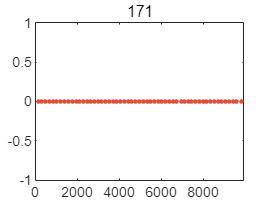


% ！！注意检查修改 ！！ %
cycle171 = 0.25+1*3+0.5;
n171 = 0;
cycle173 = 1.5-0.25+0.5;
n173 = 0;

precession = 0:70:9940;

threshold171 = 35;
threshold173 = 15;

Sz171 = (s3-s4)./(s3+s4);
Sz173 = (s1-s2)./(s1+s2);

for k = 1:(length(precession)-1)
    if (Sz171(k)*Sz171(k+1) < 0) && (precession(k) ~= precession(k+1))
        x171(n171+1) = ...
            (precession(k)*abs(Sz171(k+1))+precession(k+1)*abs(Sz171(k)))/(abs(Sz171(k))+abs(Sz171(k+1)));
        n171 = n171+1;
        cycle171 = cycle171 + 0.5;
        if n171 > 1
            if x171(n171)-x171(n171-1) < threshold171
                x171(n171) = [];
                n171 = n171-1;
                cycle171 = cycle171-0.5;
            end
        elseif n171 == 1
            if x171(n171) < threshold171/2;
                x171(n171) = [];
                n171 = n171-1;
                cycle171 = cycle171-0.5;
            end
        end
    end
    
    if (Sz173(k)*Sz173(k+1)) < 0 & (precession(k) ~= precession(k+1))
        x173(n173+1) = ...
            (precession(k)*abs(Sz173(k+1))+precession(k+1)*abs(Sz173(k)))/(abs(Sz173(k))+abs(Sz173(k+1)));
        n173 = n173+1; 
        cycle173 = cycle173+0.5;
        if n173 > 1
            if x173(n173)-x173(n173-1) < threshold173
                x173(n173) = [];
                n173 = n173-1;
                cycle173 = cycle173-0.5;
            end
        elseif n173 == 1
            if x173(n173) < threshold173/2;
                x173(n173) = [];
                n173 = n173-1;
                cycle173 = cycle173-0.5;
            end
        end
    end
end

figure;
plot(x171,zeros(n171),'.','Color',colors(1,:),'MarkerSize',8);
xlim([min(precession),max(precession)]);
title('171');

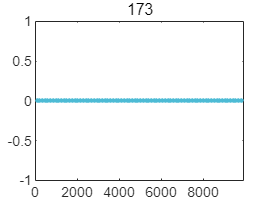

figure;
plot(x173,zeros(n173),'.','Color',colors(2,:),'MarkerSize',8);
xlim([min(precession),max(precession)]);
title('173');

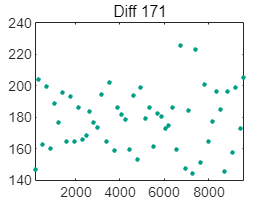


plot(x171(1:length(x171)-1),diff(x171),'.','Color',colors(3,:),'MarkerSize',8);
xlim([x171(1),x171(length(x171)-1)]);
title('Diff 171');

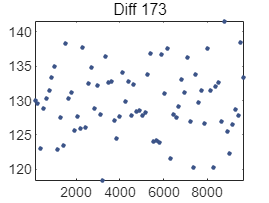

plot(x173(1:length(x173)-1),diff(x173),'.','Color',colors(4,:),'MarkerSize',8);
xlim([x173(1),x173(length(x173)-1)]);
title('Diff 173');


ratio = cycle171/cycle173;



save([main_dir_0,'\cycle.mat'],"cycle171","cycle173");


function output = diff(x)
for k = 1:(length(x)-1)
    output(k) = x(k+1)-x(k);
end
end